# ENGR 845 Mini Project Assignment: Human Activity Classification Using Smartphone Data 

The purpose of this assignment is for the students to gain hands-on experience with the concepts taught in the class including human data processing, feature engineering, pattern classification, and parameter tuning.

References: 

- Canvas -> Mini Project -> Reference Materials -> Collect Accelerometer Data from Smartphone (For Use in Matlab)

- Canvas -> Mini Project -> Reference Materials -> Adding Machine Learning to Signal Processing Application

- Canvas -> Mini Project -> Reference Materials -> EMG PR code 2.0 

- Canvas -> Weekly Lecture Slides 

Please read the instructions below and complete the required fields marked with an *. 

## Data Collection

In this assignment, 3-axis acceleration data from an iPhone 14 Pro iOS version 16.4.1 for **three** different classes of human activities are collected by myself. These motions are :-

- Activity 1 - Walking

- Activity 2 - Jumping

- Activity 3 - Sitting

**Description of how data is collected:**

- The device is placed in the left hand for the entire procedure.

- Total 4 trials are collected for each activity. The duration of each trial is 10 seconds.

- The sampling frequency for data collection is 10 Hz.

- - For Activity 1, as the "Start" button is pressed in the mobile device application of MATLAB, walking activity begins for 10 secs and Walking is recorded at a moderate speed for 10 secs in each Walking trial. Immediately after 10 secs, "stop" button is pressed to end the trial. Same has been done for activity 2 and activity 3 that is Jumping and Sitting respectively. 

- Each activity has been allotted a dedicated folder named as such - "Activity 1 - Walk'. In each folder, there are 4 trials of the particular activity named as such - "Walk1.mat". All-in-all, the data trials are named as follows:-

               --> "Activity 1 - Walk" ==> Trials - "Walk1.mat", "Walk2.mat" and so on.

               --> "Activity 2 - Jump" ==> Trials - "Jump1.mat", "Jump2.mat" and so on.

               --> "Activity 3 - Sit" ==> Trials - "Sit1.mat", "Sit2.mat" and so on.

**Dataset Preparation**

The dataset is located in the MobileSensorData folder. For each activity class, there are ***sitting.mat,walking.mat,jumping.mat*** files stored in the folder.

In this assignment, we create two sub-folders ***MobileSensorData/Train*** and ***MobileSensorData/Test*** to partition the dataset into training and testing sets. Specifically, files with names ***Sit1.mat, Sit2.mat, Walk1.mat, Walk2.mat, Jump1.mat, Jump2.mat and so on ***are stored in the train folder, while files with names ***sit1.mat, sit2.mat, walk1.mat, walk2.mat, jump1.mat, jump2.mat and so on*** are stored in the test folder.

#### Raw Data at a glance

*Please write MATLAB code to plot some example trials for the activities

w = load('Walk4.mat');

Error using load
'Walk4.mat' is not found in the current folder or on the MATLAB path, but exists in:
    /MATLAB Drive/Train

Change the MATLAB current folder or add its folder to the MATLAB path.

j = load('Jump4.mat');
s = load('Sit4.mat');


x = w.Acceleration.X;
y = w.Acceleration.Y;
z = w.Acceleration.Z;
timestamp = w.Acceleration.Timestamp;


x1 = j.Acceleration.X;
y1 = j.Acceleration.Y;
z1 = j.Acceleration.Z;
timestamp1 = j.Acceleration.Timestamp;


x2 = s.Acceleration.X;
y2 = s.Acceleration.Y;
z2 = s.Acceleration.Z;
timestamp2 = s.Acceleration.Timestamp;



combinedAccel = sqrt(x.^2+y.^2+z.^2);
combinedAccel1 = sqrt(x1.^2+y1.^2+z1.^2);
combinedAccel2 = sqrt(x2.^2+y2.^2+z2.^2);
t = zeros(size(timestamp));
t1 = zeros(size(timestamp1));
t2 = zeros(size(timestamp2));

for n = 1 : length(timestamp)
  t(n) = seconds(timestamp(n) - timestamp(1));
end

for n = 1 : length(timestamp1)
  t1(n) = seconds(timestamp1(n) - timestamp1(1));
end

for n = 1 : length(timestamp2)
  t2(n) = seconds(timestamp2(n) - timestamp2(1));
end

figure
plot(t, combinedAccel, 'g')
hold on
plot(t1, combinedAccel1, 'b')
hold on
plot(t2, combinedAccel2, 'r')
hold off

xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

**Plot for Raw data 1 : **

Walk - Green

Jump - Blue 

Sit - Red

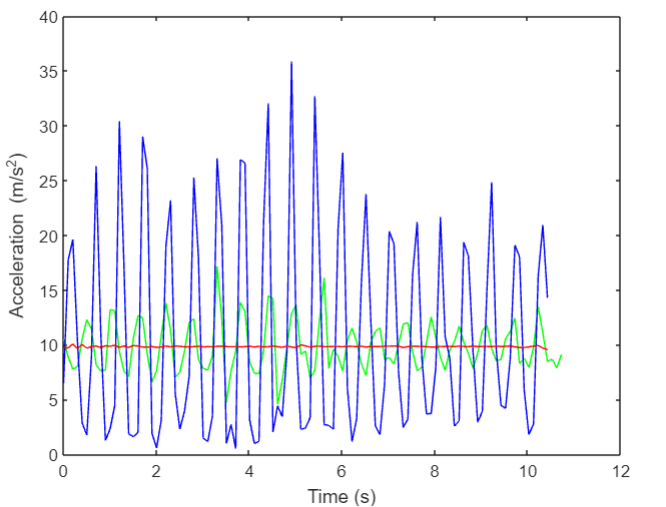

**Plot for Raw data 2 : **

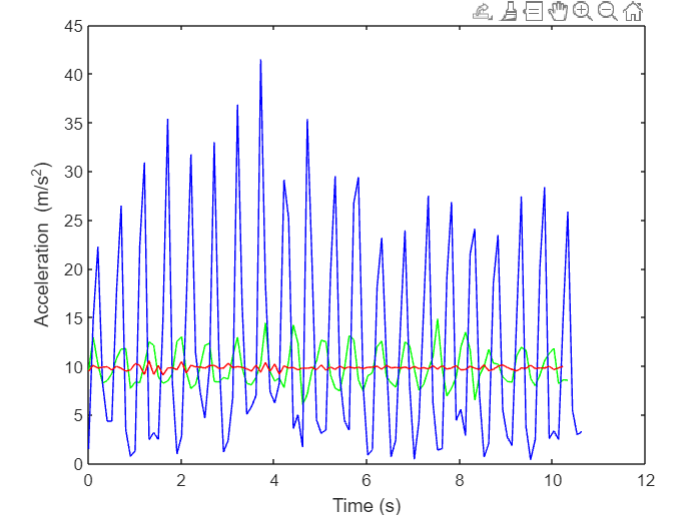

**Plot for Raw data 3 :**

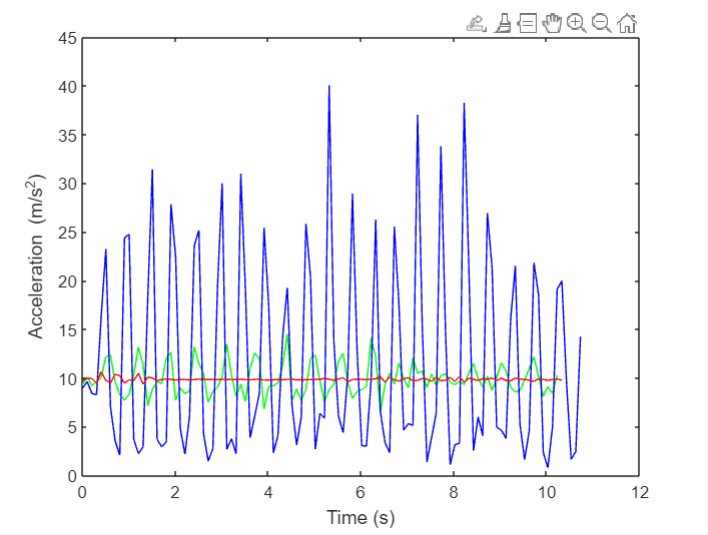 

**Plot for Raw data 4 : **

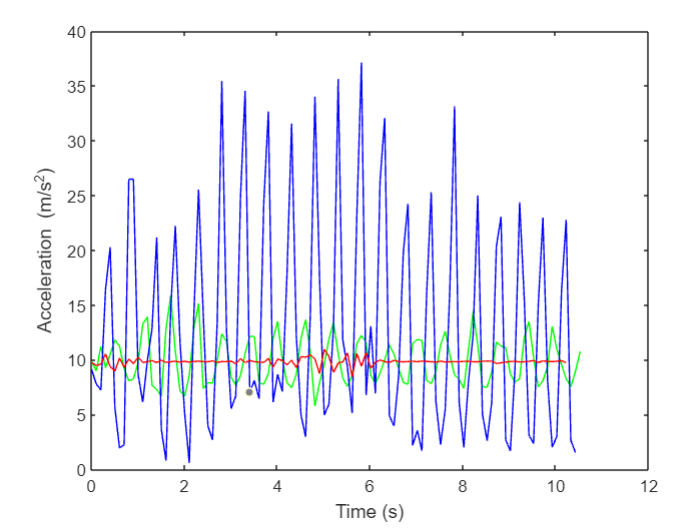

## Feature Extraction

The Raw data is segmented by analysis windows and three different combinations of  window length and window increment used are as follows 

**(1) WL = 150 ; WInc = 15 **

**(2) WL = 200 ; WInc = 20 **

**(3) WL = 50 ; WInc = 5 **

The three features extracted were as follows :

**(1) **Name of feature** : Mean **

     Formula for feature : **Mean = (x₁ + x₂ + ... + xₙ) / n where x₁, x₂, ..., xₙ are the 'n' different numbers in the set.**

     MATLAB Code to implement Formula :

            % Calculate Mean Values
            X_axis(j,i) = mean(a(st:en,1)); % X axis
            Y_axis(j,i) = mean(a(st:en,2)); % Y axis
            Z_axis(j,i) = mean(a(st:en,3)); % Z axis

**(2) **Name of feature** : Root Mean Square (rms) **

     Formula for feature : **RMS = sqrt((1/N) * sum(x^2))**

     MATLAB Code to implement Formula :

            % Calculate RMS values
            X_axis_rms(j,i) = rms(a(st:en,1)); % X axis
            Y_axis_rms(j,i) = rms(a(st:en,2)); % Y axis
            Z_axis_rms(j,i) = rms(a(st:en,3)); % Z axis

**(3) **Name of feature** : Standard Deviation (std)**

     Formula for feature : **std = sqrt [ (sum from i=1 to n of (xi - x̄)²) / (n - 1) ]**

**     where x₁, x₂, ..., xₙ are the n numbers in the set, x̄ is the sample mean of the set (calculated as the sum of the values divided by n), / denotes division, ² denotes squaring, and sqrt denotes taking   the square root.**

     MATLAB Code to implement Formula :

            % Calculate standard deviation values
            X_axis_std(j,i) = std(a(st:en,1)); % X axis
            Y_axis_std(j,i) = std(a(st:en,2)); % Y axis
            Z_axis_std(j,i) = std(a(st:en,3)); % Z axis

Here is the matlab code to implement feature extraction to the original dataset.

 % Data collected from smartphone accelerometer
%Train Data%
clear;

load('raw_data_combined.mat','combined_train_tt');
load('time_combined.mat','train_time');

a = table2array(combined_train_tt);
t = train_time;

wl = 200; % window length
wi = 20;  % window increment

win = floor((size(a,1)-wl)/wi); % Number of windows
X_axis = zeros(win,3);       % Initialize feature matrices
Y_axis = zeros(win,3);
Z_axis = zeros(win,3);

% Extract features for each activity
for i = 1:3
    if i == 1
        start_idx = 1;
        end_idx = 421;
    elseif i == 2
        start_idx = 422;
        end_idx = 846;
    else
        start_idx = 847;
        end_idx = 1261;
    end
    
    st = start_idx;
    en = start_idx + wl - 1;
    
    for j = 1:win
        if en <= end_idx % check if end index is within bounds
            X_axis(j,i) = mean(a(st:en,1)); % X axis
            Y_axis(j,i) = mean(a(st:en,2)); % Y axis
            Z_axis(j,i) = mean(a(st:en,3)); % Z axis

            % Calculate RMS values
            X_axis_rms(j,i) = rms(a(st:en,1)); % X axis
            Y_axis_rms(j,i) = rms(a(st:en,2)); % Y axis
            Z_axis_rms(j,i) = rms(a(st:en,3)); % Z axis
            
            % Calculate standard deviation values
            X_axis_std(j,i) = std(a(st:en,1)); % X axis
            Y_axis_std(j,i) = std(a(st:en,2)); % Y axis
            Z_axis_std(j,i) = std(a(st:en,3)); % Z axis
            
            st = st + wi;
            en = en + wi;
        else % if end index is out of bounds, break loop
            break;
        end
    end
end
x1 = X_axis_rms(1:j-1,1);
x2 = X_axis_rms(1:j-1,2);
x3 = X_axis_rms(1:j-1,3);
X_axis_rms = [x1;x2;x3];

y1 = Y_axis_rms(1:j-1,1);
y2 = Y_axis_rms(1:j-1,2);
y3 = Y_axis_rms(1:j-1,3);
Y_axis_rms = [y1;y2;y3];

z1 = Z_axis_rms(1:j-1,1);
z2 = Z_axis_rms(1:j-1,2);
z3 = Z_axis_rms(1:j-1,3);
Z_axis_rms = [z1;z2;z3];

x1 = X_axis_std(1:j-1,1);
x2 = X_axis_std(1:j-1,2);
x3 = X_axis_std(1:j-1,3);
X_axis_std = [x1;x2;x3];

y1 = Y_axis_std(1:j-1,1);
y2 = Y_axis_std(1:j-1,2);
y3 = Y_axis_std(1:j-1,3);
Y_axis_std = [y1;y2;y3];

z1 = Z_axis_std(1:j-1,1);
z2 = Z_axis_std(1:j-1,2);
z3 = Z_axis_std(1:j-1,3);
Z_axis_std = [z1;z2;z3];

x1 = X_axis(1:j-1,1);
x2 = X_axis(1:j-1,2);
x3 = X_axis(1:j-1,3);
X_axis = [x1;x2;x3];

y1 = Y_axis(1:j-1,1);
y2 = Y_axis(1:j-1,2);
y3 = Y_axis(1:j-1,3);
Y_axis = [y1;y2;y3];

z1 = Z_axis(1:j-1,1);
z2 = Z_axis(1:j-1,2);
z3 = Z_axis(1:j-1,3);
Z_axis = [z1;z2;z3];


% Concatenate the feature matrices
features = [X_axis Y_axis Z_axis;X_axis_rms Y_axis_rms Z_axis_rms;X_axis_std Y_axis_std Z_axis_std];

% Generate labels
labels = [ones(1,j-1) 2*ones(1,j-1) 3*ones(1,j-1) ones(1,j-1) 2*ones(1,j-1) 3*ones(1,j-1) ones(1,j-1) 2*ones(1,j-1) 3*ones(1,j-1)]';

% Create a table for importing into Classification Learner App
CL_data = table(features, labels);


Following are the results attached for the features obtained. 

**The wave Plot :-**

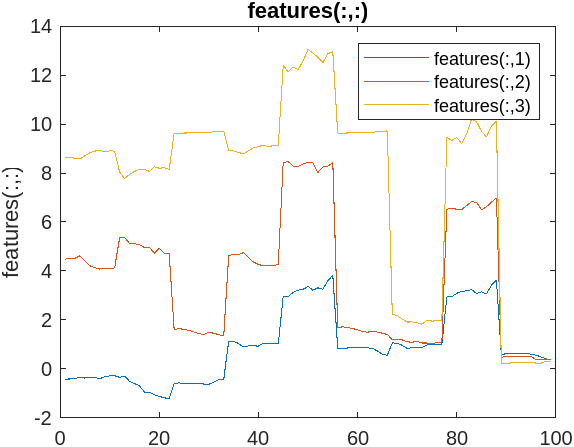

**Workspace:-**

## 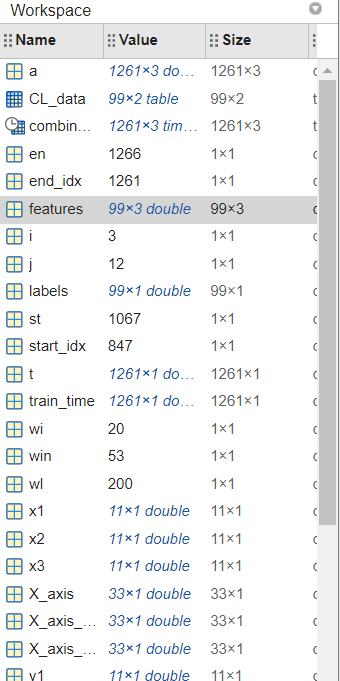

**The Feature Matrix :-**

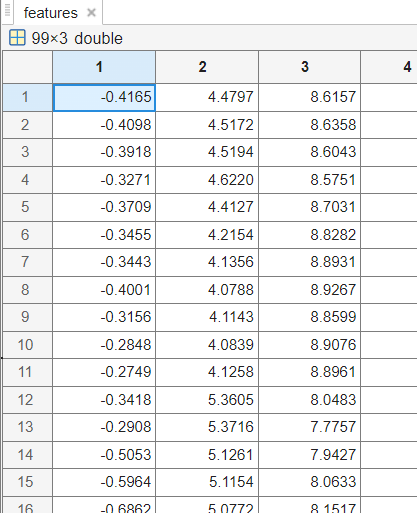

**The final output CL_data:-**

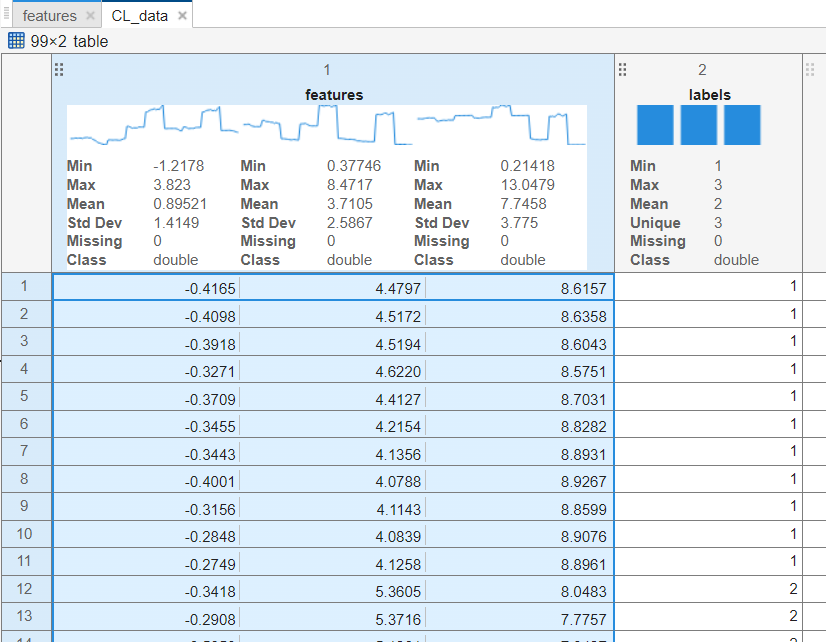

## Classification - Train a Model

Now we can train a classifier model using the feature matrix generated in the previous step. In this assignment, we use the MATLAB built-in ***Classification Learner*** app to do pattern classification. 

You can launch the ***Classification Learner*** app by running the code below or open it from the APPS menu. Please refer to the references provided at the top of this document to learn how to use the app.

classificationLearner

So, several experiments were conducted to train classifiers with different combinations of parameters and test them on the testing dataset.

## **First try: Train a classification model with original training feature set (no feature reduction)**

To do this, the CL_data matrix was added to the input. Fine tree method was implemented to train the data. CL_data_test was added as an input to the test data set and  the model was tested. This are results obtained:

This is the scatter plot of the data which shows all the 3 datasets of the all the features.

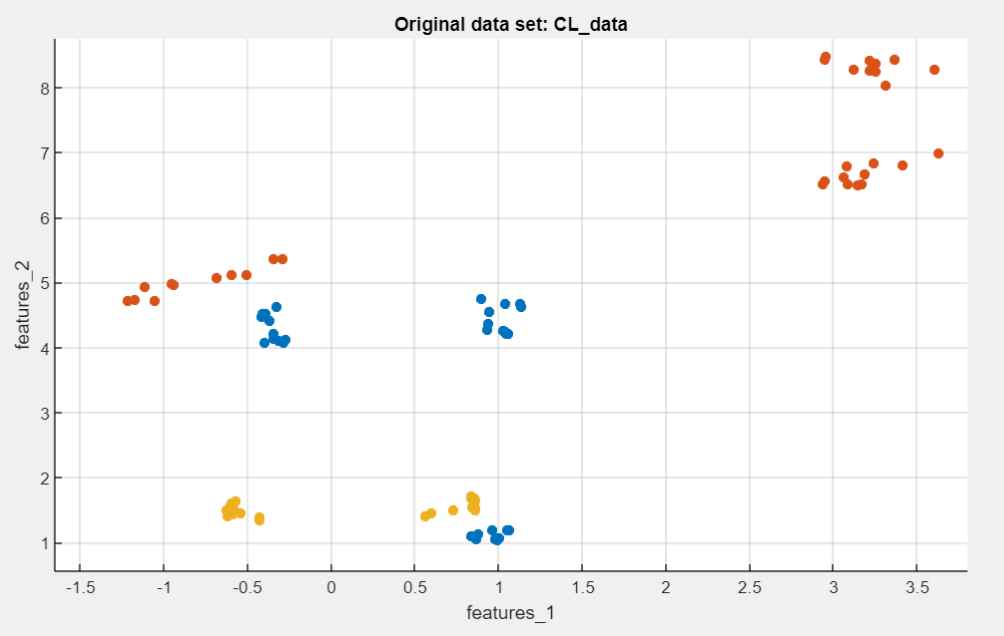

This is the confusion matrix obtained:

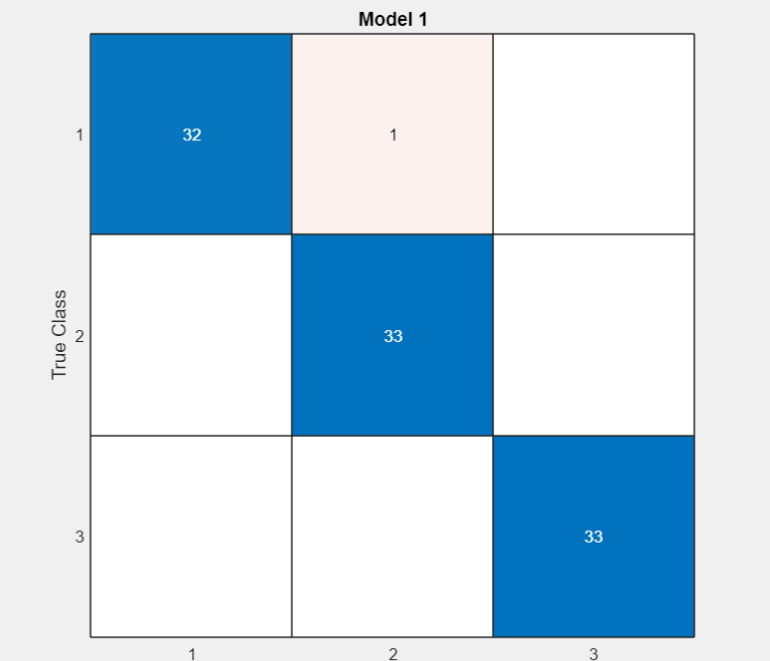

The accuracy achieved through this method was 99% for Trained data and 91.1% for test data.

## Second try: Train a classification model with original training feature set and feature reduction with PCA

For second trial, SVM Linear model was implemented to the Raw data that is the original training feature set with PCA on. The accuracy for trained and test dataset are mentioned in the summary. Following are the results obtained from same:-

The Scatter Plot - 

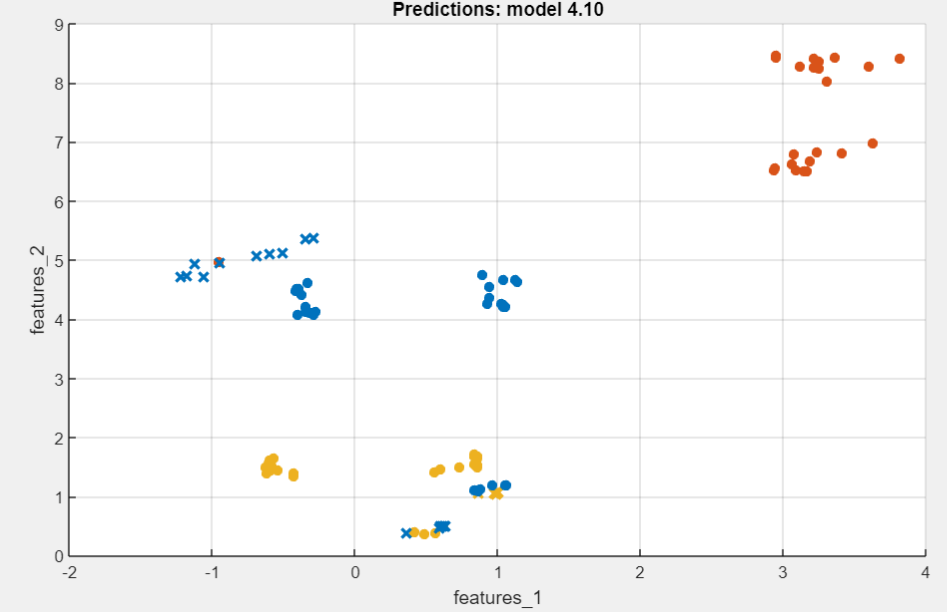

The confusion matrix - 

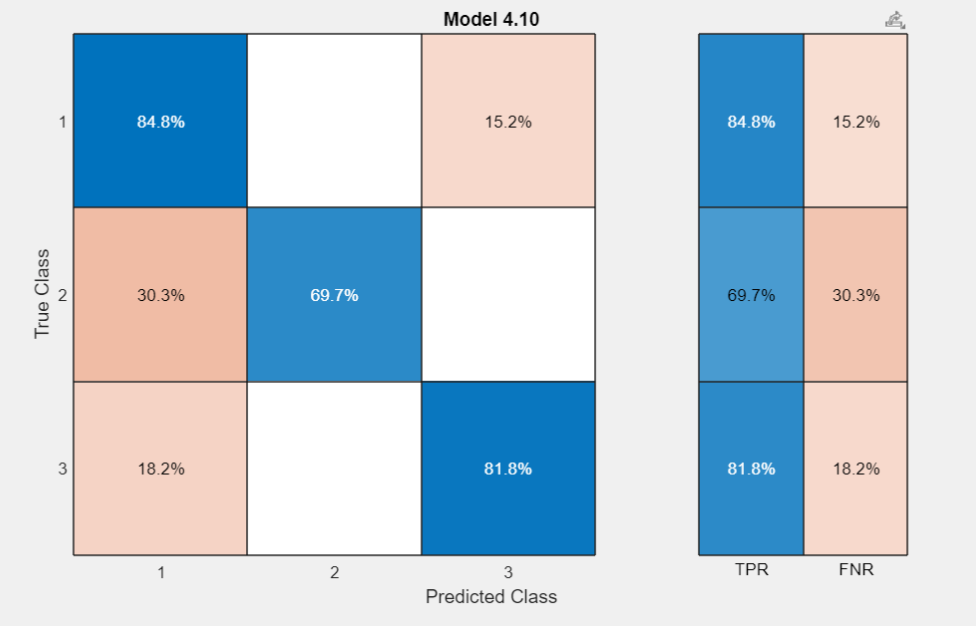

The summary:-

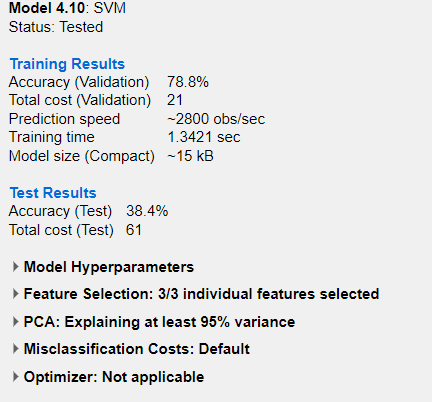

Other than that, all the parameters were implemented using "All Quick-to-train" option. This was done to check which method gives the best output. So, here is a glimpse of results obtained from all the models:

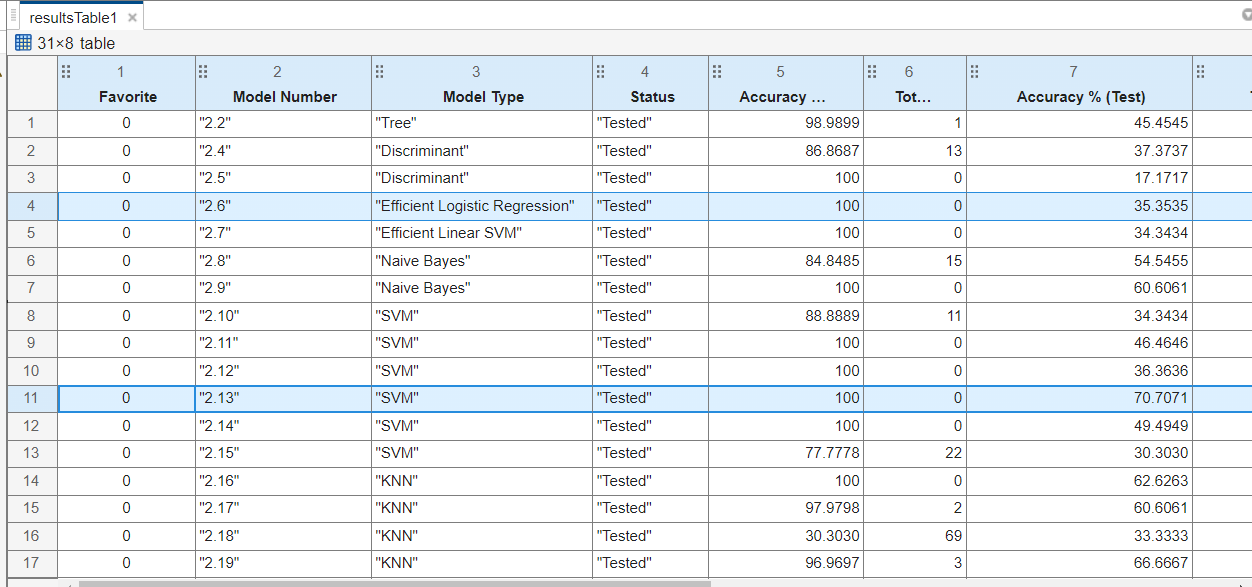

- A particular focus goes on at** model number 2.6 Fine Gaussian SVM method with PCA on**. The training accuracy was here **100%** and testing accuracy was **70.07%.** 

So here, by collecting Accelerometer Data from Smartphone through MATLAB mobile application and manipulating it to extract required features from it, we used MATLAB to process the data and also to add Machine Learning to this signal processing Application. After using ClassificationLearner App to do so, we finally concluded with a decision that SVM Linear model with feature reduction (With PCA) is the best method to implement Machne Learning to the Features extracted.

Last but not least I want to add is that we can also utilize other sensors available in MATLAB mobile App to train and add Machine Learning various other activities all through  MATLAB.